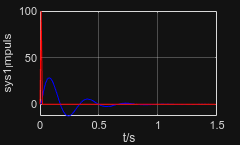

A0 = readtable("/home/jg/01-projects/RTP-T2/02_Preperations/data/sys0.csv");
A1 = readtable("/home/jg/01-projects/RTP-T2/02_Preperations/data/sys1.csv");
A2 = readtable("/home/jg/01-projects/RTP-T2/02_Preperations/data/sys2.csv");

t0=A0.t; x0=A0.x; y0=A0.y;
t1=A1.t; x1=A1.x; y1=A1.y;
t2=A2.t; x2=A2.x; y2=A2.y;

%Impulsantwort integrieren um die Sprungantwort zu bekommen
x1_sprung=cumsum(x1);
y1_sprung=cumsum(y1);


% plot(t0,x0,'b',t0,y0,'r')
% grid on;
% xlabel('t/s');
% ylabel('sys0');

plot(t1,x1,'b',t1,y1,'r')
grid on;
xlabel('t/s');
ylabel('sys1_Impuls');



% plot(t2,x2,'b',t2,y2,'r')
% grid on;
% xlabel('t/s');
% ylabel('sys2');


Bestimmung der Systemparameter Kp, D und $\omega_0$ für System 1

[Max, Index] = max(x1_sprung);
tmax = A1.t(Index);
om_d = pi/tmax;
hmax = Max;
x1_stat = x1_sprung(135:end);                   %letzte 10% der Messdaten
Kp = mean(x1_stat)                              %Mittelwert letzte 10%, weil Kp = h(unendl.)

Kp = 198.5982


ue = (hmax-Kp)/Kp;                              %Uberschwungweite ü (Gl. 3.41 Skript)
D = (abs(log(ue)))/sqrt(pi^2 + (log(ue))^2)     %Dämpfungsgrad D (Gl. 3.42)

D = 0.2455


om_0 = om_d/sqrt(1-D^2)                         %unged. Eigenkreisfrequenz 

om_0 = 19.0631

Übergangsfunktion hübsch machen -> tmax, hmax, Kp einzeichnen, evtl Hüllkurven

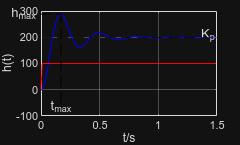

plot(t1,x1_sprung,'b',t1,y1_sprung,'r')
grid on;
hold on;
% Hilfslinien (alle gestrichelt, schwarz)
plot([tmax tmax], [-50 hmax], 'k--');  % Vertikale Linie bei tmax
plot([0 tmax], [hmax hmax], 'k--');  % Horizontale Linie bei hmax
yline(Kp, 'k--');                    % Horizontale Linie bei Kp
% Beschriftungen
text(tmax, -65, 't_{max}', 'HorizontalAlignment', 'center');
text(-0.03, hmax, 'h_{max}', 'HorizontalAlignment', 'right');
text(max(t1), Kp+10, 'K_p', 'HorizontalAlignment', 'right');
text()
xlabel('t/s');
ylabel('h(t)');